# Introduction to Predator Prey Models

## Sec 1: Classic Predator-Prey (Lotka-Volterra)

Suppose there is a population of rabbits and foxes. The rabbits eat unlimited grass while the foxes can only eat the rabbits. How can we describe how the rabbit population, $R$, chages over time? What about the fox population, $F$? How do they interact with each other?

We can write the following equations:


$$dR/dt = \alpha R - \beta RF$$



$$dF/dt = \delta RF - \gamma F$$


with the following parameters:

$\alpha$ = growth rate of rabbits

$\beta$ = death rate of rabbits

$\delta$ = growth rate of foxes

$\gamma$ = death rate of foxes

These equations describe how the populations change over time. We can solve them using $ode45$ to visualize what happens to the populations.

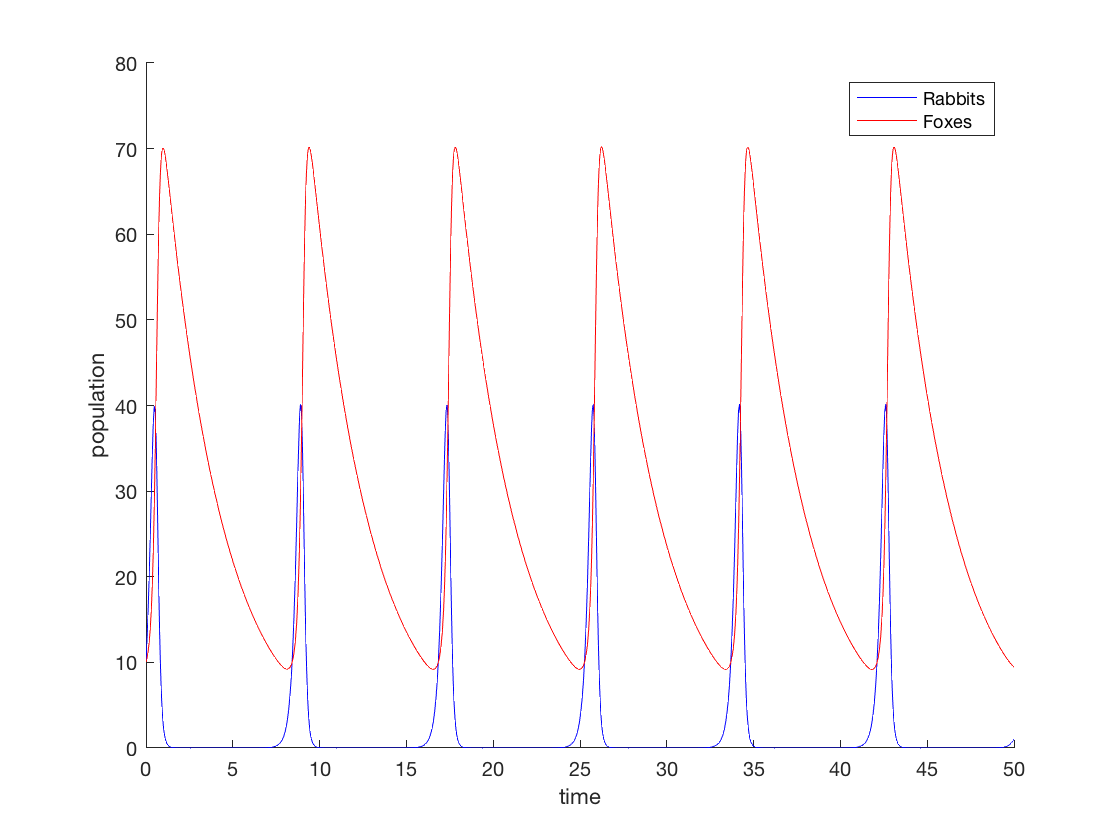

% alpha = 1.1;
% beta = 0.4;
% delta = 0.1;
% gamma = 0.4;

% set parameters (birth, death rates)
alpha = 6;
beta = 0.2;
delta = 0.1;
gamma = 0.3;

% set initial population sizes
R0 = 10;
F0 = 10;

% write system of odes
dRFdt = @(RF) [alpha*RF(1) - beta*RF(1)*RF(2); delta*RF(1)*RF(2) - gamma*RF(2)];

% solve
[t,RF] = ode45(@(t,x) dRFdt(x),[0 50],[R0;F0]);

% plot
figure; clf; hold on;
plot(t,RF(:,1),'b');
plot(t,RF(:,2),'r');
xlabel('time');
ylabel('population');
legend('Rabbits','Foxes');

## Sec 2. Rosenzweig-MacArthur model

The classic Predator-Prey model uses some assumptions which may or may not be reasonable, depending on the system being studied.

For rabbits, it seems unlikely that there is either infinite food or infinite space for them to live. For the foxes, it's unlikely that their stomachs can perpetually eat rabbits without getting full.

It's fairly straightforward to modify the original model to account for new limitations such as these.

These particular limitations are introduced in the Rosenzweig-MacArthur extension of predator-prey:


$$dR/dt = R\left(1-\frac{R}{K}\right) - F\left(\frac{R}{1+R}\right)$$



$$dF/dt = \delta F\left(\frac{R}{1+R}\right) - \gamma F$$


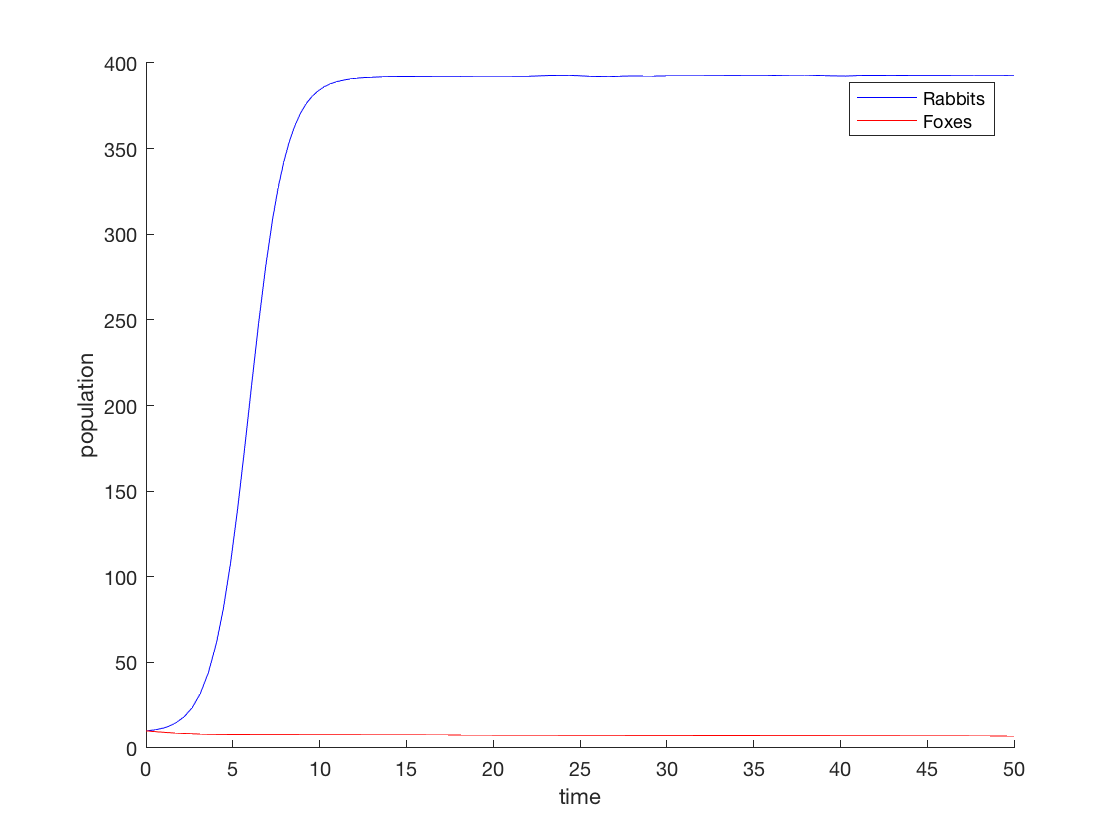

% set parameters (birth, death rates)
K = 400;
m = 1;
c = 1;

% set initial population sizes
R0 = 10;
F0 = 10;

% write system of odes
%dRFdt = @(RF) [alpha*(1-RF(1)/K)*RF(1) - beta*(RF(1)/(1+eta*beta*RF(1)))*RF(2); delta*(RF(1)/(1+eta*beta*RF(1)))*RF(2) - gamma*RF(2)];
dRFdt = @(RF) [(1-RF(1)/K)*RF(1) - m*(RF(1)/(1+RF(1)))*RF(2); m*(RF(1)/(1+RF(1)))*RF(2) - c*RF(2)];


% solve
[t,RF] = ode45(@(t,x) dRFdt(x),[0 50],[R0;F0]);

% plot
figure; clf; hold on;
plot(t,RF(:,1),'b');
plot(t,RF(:,2),'r');
%ylim([0 100]);
xlabel('time');
ylabel('population');
legend('Rabbits','Foxes');

Note: What happens when you increase $K$? Does this make sense?